# 利用PSYCHTOOLBOX生成视觉刺激

  问题22：从介观水平看，基于视网膜注意存在perceptual cycle吗？

  问题23：视角的概念和应用（误用）列举？

  问题24：Image,imagesc与colormap的关系是怎样的？

  问题25：为什么说MATLAB比photoshop有过之而无不及？

  问题26：心理学的三原色是什么，如何构造和应用？ 

##  要点

- PTB的数据类型 

- 初识Screen函数

- 视角概念和计算 

- 空间和颜色控制

问题22: 从介观水平看，基于视网膜注意存在perceptual cycle吗？

Fakche C, Dugué L. Perceptual Cycles Travel Across Retinotopic Space.  Journal of Cognitive Neuroscience. 2024 Jan;36(1):200-216. DOI:  10.1162/jocn_a_02075

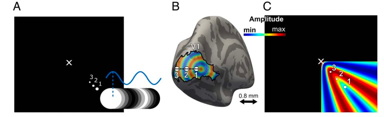

﻿ 

问题23：视角的概念和应用（误用）列举？ 

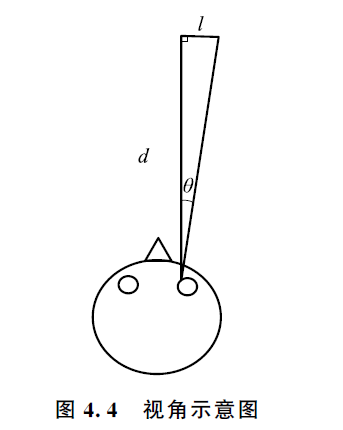

function pixs=deg2pix(degree,inch,pwidth,vdist,ratio) 
% parameters: degree, inch (monitor size), pwidth (width in pixels), 
% vdist: viewsing distance
% ratio: ration = pheight/pwidth   
screenWidth = inch*2.54/sqrt(1+ratio^2);  % calculate screen width in cm 
pix=screenWidth/pwidth; %wRect(3); %calculates the size of a pixel in cm  
pixs = round(2*tan((degree/2)*pi/180) * vdist / pix); 

%%
url='http://psychtoolbox.org/docs/PsychDemos'
web(url)
Screen('Version')

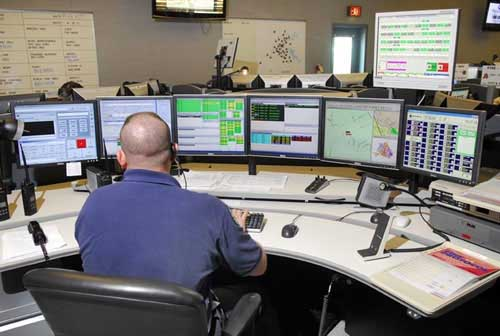

## Screen函数: Screens子函数

### Screens 子函数： 查询有多少屏幕

### FAQ: 有多少屏幕？ 

- 若有多个显示器， 一般主屏幕用来控制， 编号最大的屏幕用来呈现刺激

- 此步可省略， 可以直接开0号窗口

screens=Screen('Screens'); 
screenNumber=max(screens);  % 拓展屏的编号一般大于主屏幕

## PTB打开和关闭屏幕

Screen('OpenWindow?')
Screen OpenWindow?

Screen('CloseAll') 

[windowPtr, rect]=Screen(‘Openwindow’,windowPtrOrScreenNumber, [, color],[, rect],[, pixelSize],[,numberOfBuffers] [,stereomode] [, multisample] [, imagingmode] [, specialFlags ], [, clientRect]);

## 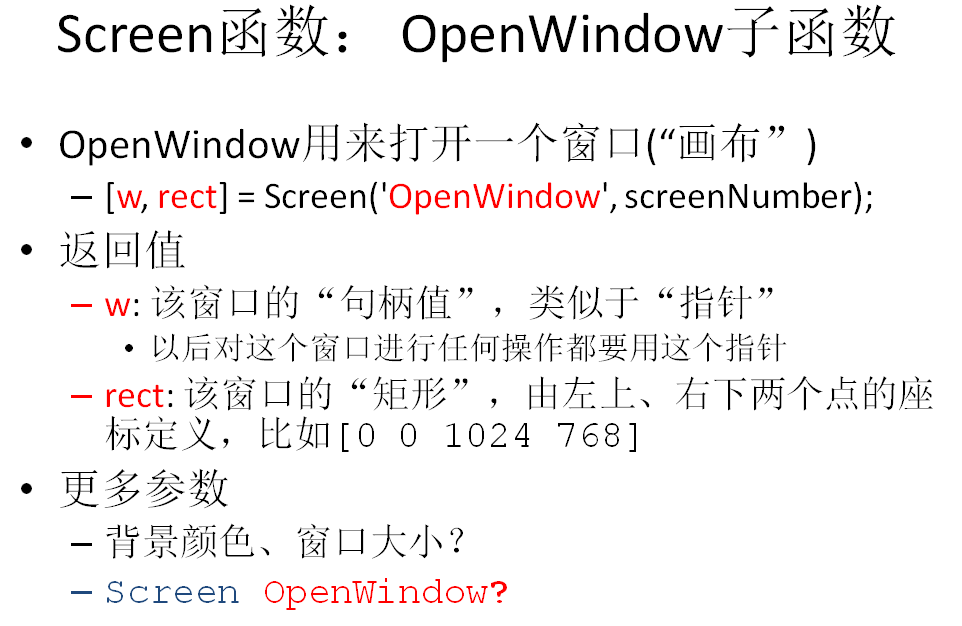

## 窗口的空间控制

获取窗口的一些信息

Screen('Resolutions',0)
Screen('DisplaySize',0)
Screen('WindowSize',0)
get(0,'ScreenSize')
get(0,'MonitorPositions') %  It returns the width and height of primary and secon

 打开一个黑色的窗口

try
    Screen('Preference', 'SkipSyncTests', 1); 
    w=Screen('OpenWindow',0,128); % 打开一个窗口
    WaitSecs(2);  % 等待时间，以秒为单位；这里理论上等待2秒
    Screen('CloseAll');
catch
    Screen('Close', w)
    rethrow(lasterror)
end

PTB中空间位置绝大多数都是通过坐标表示

坐标起始点(0,0)为**左上角，横向为x轴，纵向为y轴，坐标的单位为像素**

打开局部窗口，显示"PSYCHTOOLBOX"

try
    Screen('Preference', 'SkipSyncTests', 1); 
    [w, Rect]=Screen('OpenWindow',0,128,[120,120,500,500]); % 打开一个窗口
    % 通过给Screen('OpenWindow')指定rect参数打开局部窗口,这里的坐标为显示器左上角
    Screen('DrawText',w,'PSYCHTOOLBOX',120,200,[255,0,0])
    % 通过给Screen('DrawText')指定x,y参数在指定位置显示,这里的坐标为打开的屏幕的左上角
    Screen('Flip',w);
    WaitSecs(2);  % 等待时间，以秒为单位；这里理论上等待2秒
    Screen('CloseAll');
catch
    Screen('Close', w)
    rethrow(lasterror)
end

## 窗口的颜色控制

Screen('OpenWindow')文档中对于颜色的说明:

“color” is the clut index (scalar or [r g b] triplet or [r g b a] quadruple) that you want to poke into each pixel; default color is white.

Screen很多其他子函数也接受类似的color参数

使用单一数值指定颜色时，一般0为黑色,数值越大越偏向白色

打开一个白色的局部窗口

try
    clear all;
    % 定义黑白颜色
    white = WhiteIndex(0);
    black = BlackIndex(0);
    Screen('Preference', 'SkipSyncTests', 1); 
    w=Screen('OpenWindow',0,white,[120,120,500,500]);  
    WaitSecs(2);  % 等待时间，以秒为单位；这里理论上等待2秒
    Screen('CloseAll');
catch
    Screen('Close', w)
    rethrow(lasterror)
end

使用RGB三维数组，打开一个蓝色的局部窗口

try
    Screen('Preference', 'SkipSyncTests', 1); 
    w=Screen('OpenWindow',0,[0 0 255],[120,120,500,500]); 
    % 打开一个灰色窗口
    WaitSecs(2);  % 等待时间，以秒为单位；这里理论上等待2秒
    Screen('CloseAll');
catch
    Screen('Close', w)
    rethrow(lasterror)
end

  问题24：Image,imagesc与colormap的关系是怎样的？

% 创建一个矩阵
matrix = magic(5); % 使用magic函数生成一个5x5的幻方矩阵

% 使用imagesc显示矩阵
figure; % 创建一个新的图形窗口
%image(matrix);
imagesc(matrix); % 显示矩阵
title('Default Colormap'); % 添加标题
colorbar; % 显示颜色条

% 改变colormap为jet
figure; % 创建另一个新的图形窗口
imagesc(matrix); % 再次显示矩阵
colormap('jet'); % 改变颜色映射为jet
title('Jet Colormap'); % 添加标题
colorbar; % 显示颜色条

% 改变colormap为gray
figure; % 创建又一个新的图形窗口
imagesc(matrix); % 再次显示矩阵
colormap('gray'); % 改变颜色映射为灰度
title('Gray Colormap'); % 添加标题
colorbar; % 显示颜色条

  问题25：为什么说MATLAB比photoshop有过之而无不及？

% 读取图像
img = imread('keklike.jpg'); % 替换'your_image_path.jpg'为你的图像文件路径

% 转换为灰度图像
grayImg = rgb2gray(img);

% 使用Sobel算子进行边缘检测
edgeImg = edge(grayImg, 'sobel');

% 显示原图和边缘检测后的图像
figure;
subplot(1,2,1), imshow(img), title('Original Image');
subplot(1,2,2), imshow(edgeImg), title('Edge Detected Image');

  双眼竞争

im1=imread('lihan.jpg');
im2=imread('office.jpg');
im1(:,:,1)=im2(:,:,1);
im1(:,:,2)=0;
imshow(im1);

问题26：心理学的三原色是什么，如何构造和应用？ 

% 初始化Psychtoolbox
PsychDefaultSetup(2);
screens = Screen('Screens');
screenNumber = max(screens);

% 定义颜色
red = [255 0 0];
green = [0 255 0];
blue = [0 0 255];

% 打开一个窗口
[window, windowRect] = Screen('OpenWindow', screenNumber, 0);
[screenXpixels, screenYpixels] = Screen('WindowSize', window);
Screen('TextSize', window, 40);
Screen('Preference', 'SkipSyncTests', 1); 
% 计算每个颜色区域的位置
width = screenXpixels / 3;
height = screenYpixels;
yCenter = height / 2;
% 定义每个颜色区域的矩形坐标
redRect = [0 0 width height];
greenRect = [width 0 width*2 height];
blueRect = [width*2 0 screenXpixels height];

% 绘制三原色
Screen('FillRect', window, red, redRect);
Screen('FillRect', window, green, greenRect);
Screen('FillRect', window, blue, blueRect);

% 在每个颜色区域添加文字标签
Screen('DrawText', window, 'Red', width/4, yCenter, 0);
Screen('DrawText', window, 'Green', width + width/4, yCenter, 0);
Screen('DrawText', window, 'Blue', width*2 + width/4, yCenter, 0);

% 显示结果
Screen('Flip', window);

% 等待键盘输入
KbStrokeWait;

% 关闭窗口
sca;

%% PTB - Screen

%% how to open a window
% Check if PTB-3 is properly installed on the system
AssertOpenGL;

% 获取当前的所有显示器，返回序列
screens = Screen('Screens');

% 选择其中一个显示器
screenNumber = max(screens);

% 获得该显示器的参数，用于计算实验刺激的大小
[winwidth, winheight]=Screen('DisplaySize', screenNumber); % 设备报告给操作系统的显示器物理大小，单位为mm；用于计算实验刺激的大小（macOS上可能会存在问题
resolution = Screen('Resolution', screenNumber); % 获取显示器当前的显示分辨率，返回struct结构变量
inch = (winwidth^2+winheight^2)^0.5/25.4; % 显示器尺寸，单位为英寸

% 窗口大小设置，不设置则默认为全屏
ratio = 1;
Rect = [0 0 ratio*resolution.width ratio*resolution.height]; % 窗口大小，(0,0)规定了窗口左上顶点的位置，（0.5*resolution.width，0.5*resolution.height）规定了窗口右下顶点的位置

% 打开窗口的背景颜色，默认为白色
white = [255 255 255];
bkcolor = white;

% 跳过同步性检验，正常实验不跳过
Screen('Preference','SkipSyncTests',1);

% 提高优先级
Priority(0);

% 在左上角打开占屏幕1/4的窗口。该方式适合debug，正常实验则需要全屏显示
[win,winRect]=Screen('OpenWindow',screenNumber, bkcolor);%Rect); % 打开窗口，返回窗口指针和窗口大小

% 获取窗口的像素大小
[screenXpixels, screenYpixels] = Screen('WindowSize', win); % 一般情况下screenXpixels = winRect(3)-winRect(1); screenYpixels = winRect(4)-winRect(2);

% 获取窗口的中心
[xcenter, ycenter] = RectCenter(winRect);  % 获取矩阵的中心点
% 如果返回的窗口左上顶点是(0,0)，那也可以xcenter = winRect(3)/2; ycenter = winRect(4)/2;

% 获取屏幕刷新时间
flipInv = Screen('GetFlipInterval', win);

try
% display something on your window

%%  窗口中心画一个大小为2°的十字架注视点 DrawLine

%%% 视角计算
fixLen = 2; % 视角为2°
vdist = 50; % 视距，假设为50cm
fixLen = deg2pix(fixLen,inch,screenXpixels,vdist,winheight/winwidth);

lineWidth = 4; % 线条宽度
black = [0 0 0]; % 线条颜色
Screen('DrawLine', win, black, xcenter-fixLen/2, ycenter, xcenter+fixLen/2, ycenter, lineWidth); % 画入缓冲器-横线
Screen('DrawLine', win, black, xcenter, ycenter-fixLen/2, xcenter, ycenter+fixLen/2, lineWidth); % 画入缓冲器-横线
Screen('Flip',win); % 从缓冲器里刷新出来
WaitSecs(3);

% 关闭窗口
Screen('CloseAll');

catch me
    Screen('CloseAll');
    disp(me)
    disp(me.stack)
end